# Grid of cells (2DOF)

clear; close all; clc;
set_env;
addpath("2DOF\");
load('2DOF\cell_2dof_pstrain.mat')
load('2DOF\cell_2dof_pstress.mat')
load('2DOF\res_2dof_pstrain.mat')


% Data --------------------------------------------------------------
% Constants

% Symbolic variables ------------------------------------------------
% Data
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f l_0 w_0 tp_0 tf_0 xi_0 x l_c
syms d P_t Vtank f
syms p_atm T_std gamma_air rhostd_air c_v c_p
% New variables
syms T(x_t) p(x_t) rho_0 Vc_0 T_0 Vf_tot

% Physical quantities
syms V Fc(x,V)


## Single cell quantites

pstrain = sstrain2(pstrain_2dof, 'PSTRAIN');
Vol_fcell = 2 * pstrain.Vol_f; 
Vol = 2 * pstrain.Vol;
Uel_xmax_fullrange = 2 * res_2dof_pstrain.Uel_xmax;
uel_xmax_fullrange = res_2dof_pstrain.uel_xmax;

int_F = @(x,V) 2 * res_2dof_pstrain.int_F(double(x),double(V));
int_lc = @(x,V) res_2dof_pstrain.int_lc(double(x),double(V));
x_range_ref = res_2dof_pstrain.x_range_ref;
x_range_norm = double(x_range_ref / sdata2(l_0));
V_range = res_2dof_pstrain.V_range;
C = 2 * pstrain.C1;

myfig(1, "U_{el} and u_{el}");

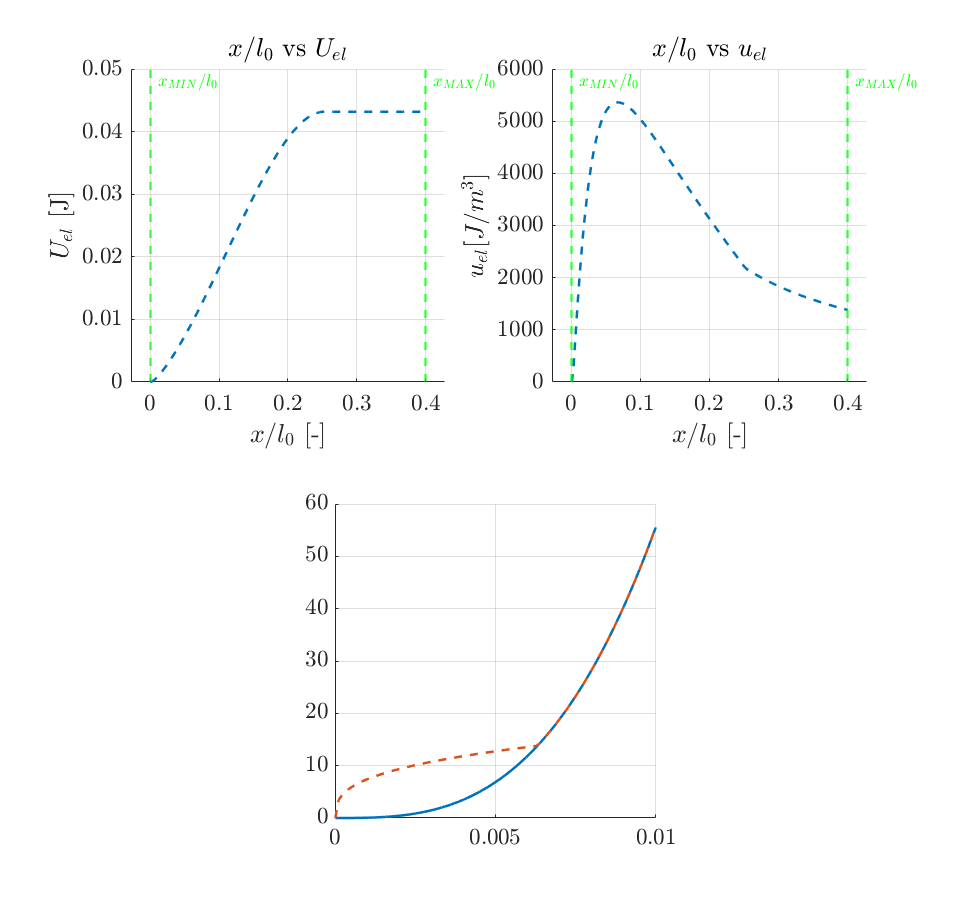

subplot(2,2,1); hold on
plot(x_range_ref / sdata2(l_0), Uel_xmax_fullrange, '--')
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$U_{el}$ [J]", "$x / l_0$ vs $U_{el}$")
xlim("padded")

subplot(2,2,2); hold on
plot(x_range_ref / sdata2(l_0), uel_xmax_fullrange, '--')
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$u_{el} [J/m^3]$", "$x / l_0$ vs $u_{el}$")
xlim("padded")

subplot(2,2,3.5); hold on
plot(x_range_ref, int_F(x_range_ref, V_range(1)))
plot(x_range_ref, int_F(x_range_ref, V_range(end)), '--')

plot_xminmax(x_range(1), x_range(end))

Unrecognized function or variable 'x_range'.

addlabels("$x$ [m]", "$ F(x) [N]$", "$x$ vs $F$")
xlim("padded")

% Fix x_max
x_min = x_range_ref(1);
x_max = double(0.3 * sdata2(l_0));
x_range = x_min:1e-5:x_max;
x_range_norm = double(x_range / sdata2(l_0));
Uel_xmax = interp1(x_range_ref, Uel_xmaxcell, x_range);
uel_xmax = interp1(x_range_ref, uel_xmaxcell, x_range);
max_uel = max(uel_xmax);
%

myfig(2, "U_{el} and u_{el}");
subplot(2,2,1); hold on
plot(x_range / sdata2(l_0), Uel_xmax)
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$U_{el}$ [J]", "$x / l_0$ vs $U_{el}$")
xlim("padded")

subplot(2,2,2); hold on
plot(x_range_norm, uel_xmax)
plot_xminmax(x_range_norm(1), x_range_norm(end), "$x_{MIN} / l_0$", "$x_{MAX} / l_0$")
addlabels("$x / l_0$ [-]", "$u_{el} [J/m^3]$", "$x / l_0$ vs $u_{el}$")
xlim("padded")

subplot(2,2,3.5); hold on
plot(x_range, int_F(x_range, V_range(1)))
plot(x_range, int_F(x_range, V_range(end)), '--')
plot_xminmax(x_range(1), x_range(end))
addlabels("$x$ [m]", "$ F(x) [N]$", "$x$ vs $F$")
xlim("padded")


## Grid design

% p * V^gamma_air = const
% T * V^(gamma-1) = const
% T * p^((1-gamma)/gamma) = const

syms m_a
m_a = vpa(sdata2(solve(P_t == max_uel * f * m_a, m_a)))

Unrecognized function or variable 'max_uel'.

N = vpa(500)
NrNc = [divisors(N)',N./divisors(N)'];
N_r = NrNc(length(NrNc) / 2, 1)
N_c = NrNc(length(NrNc) / 2, 2)

% x_t = N_r * x;
xt_0 = vpa(N_r * x_range(ceil(end/2)))
 
% Vc_0 (gas volume)
% if x = 0 , Vc = 0, Vf = Vtank
% if x = xt_0 / N_r , Vc = 0

% p_0, rho_0, Vc_0, T_0
eq_pFel = (p - p_atm) * pi / sym(4) * d^2 == Fc(xt_0 / N_r, V_range(end)) * N / N_r;
p_0 = vpa(subs(sdata2(rhs(isolate(eq_pFel, p(x_t)))), Fc, int_F(xt_0 / N_r, V_range(end))))

Vc_0 = subs(sdata2(Vtank - (Vf_tot - N * subs(Vol_fcell, x, xt_0 / N_r))), l_c, int_lc(xt_0 / N_r, V_range(end)))
V_c = Vc_0 + pi / 4 * d^2 * (x_t - xt_0);
Vol_ftank = Vtank - V_c;

T_0 = sdata2(solve_adiab(p_0, T_std, p_atm, 'tp'))
pc = solve_adiab(V_c, p_0, Vc_0, 'pV')
Ugas = rho_0 * Vc_0 * c_v * T

F = sdata2(N / N_r * Fc(x_t / N_r, V_range(end)) - (pc - p_atm) * pi / 4)


xt_range = 0:1e-5:x_max;
Fvec = subs(F, {Fc(x_t / N_r, V_range(end)), x_t}, {F_cell(x_range(1) + xt_range / N_r, V_range(end)), xt_range});
myfig(3, "x_t vs F")
plot(xt_range, Fvec)
addlabels("$x_t [m]$", "F [N]", "$x_t$ vs F")


